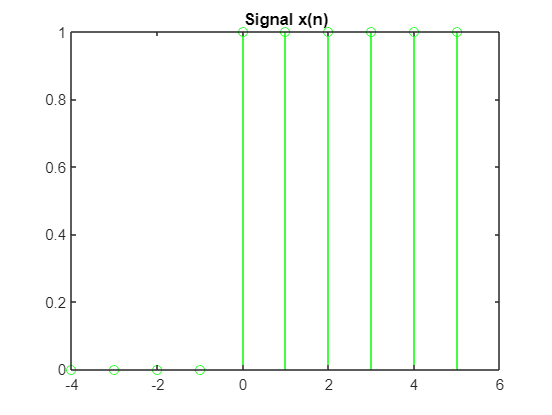

% Signal Input x(n)
N=-4:1:5; %muestras
xn=(N>=0);
stem(N,xn, 'g')
%Graffic = stem(N,xn, 'g')
title('Signal x(n)')

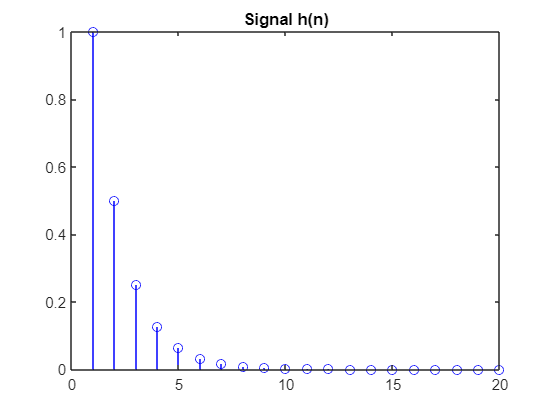


% Signal h(n)
N1=20;
Amp=0.5;
hn=Amp.^(0:N1-1);
stem(hn, 'b')
title('Signal h(n)')

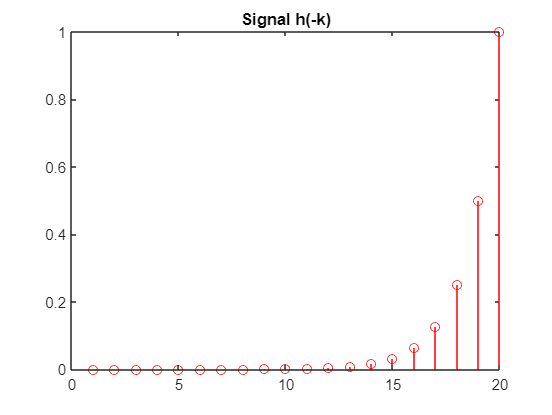


% Signal h(-n)
Signalhk1=fliplr(hn);
stem(Signalhk1,'r')
lhk=length(Signalhk1);
lxn=length(xn);
title('Signal h(-k)')

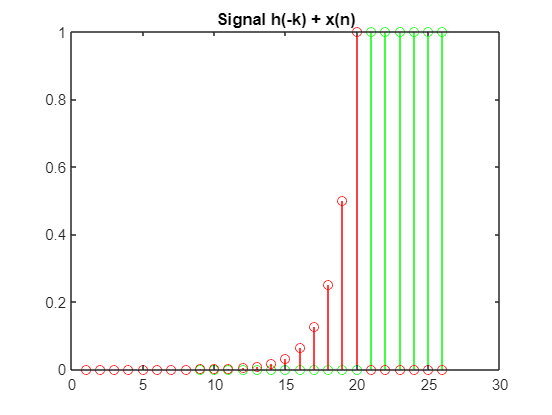


%Signal x(n) y h(-k) 
Signalhk2=[Signalhk1 zeros(1,lxn-4)];
xn2=[zeros(1,lhk-4) xn];

stem(xn2, 'g')
hold on
stem(Signalhk2,'r')
hold off
title('Signal h(-k) + x(n)')

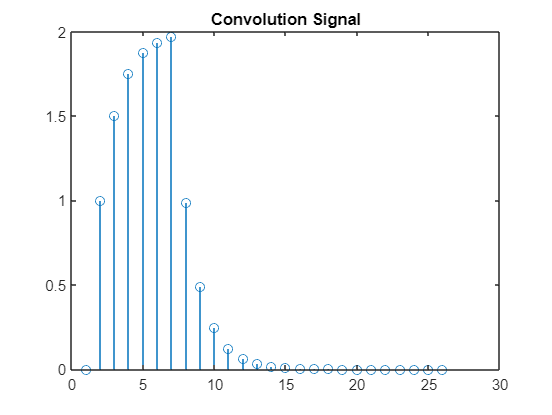


lSignalhk2=length(Signalhk2);
for n=1:lSignalhk2
yn(n)=sum(xn2.*Signalhk2);
Signalhk2=[0 Signalhk2(1:end-1)];
end

stem(yn,'o') 
title('Convolution Signal')


t1 = 0:1:28;
Convol = conv(hn,xn)

Convol =          0         0         0         0    1.0000    1.5000    1.7500    1.8750    1.9375    1.9688    0.9844    0.4922    0.2461    0.1230    0.0615    0.0308    0.0154    0.0077    0.0038    0.0019    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000


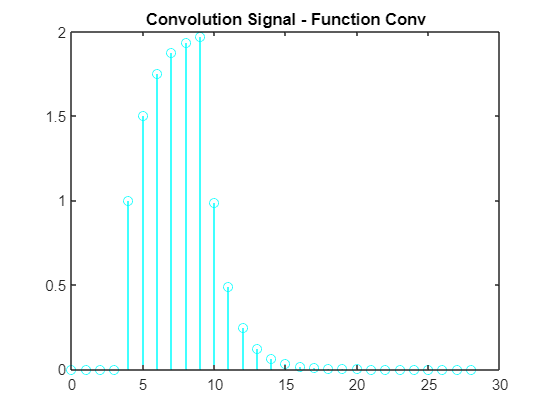

stem(t1,Convol, 'c')
title('Convolution Signal - Function Conv')